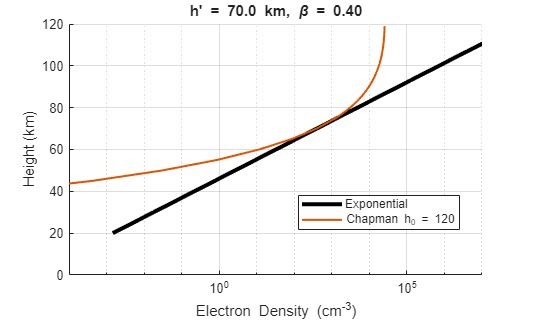

hprime = 70;
beta = 0.4;
h_0 = 120;
ym = 20;

qe = 1.602176634e-19; %C
eps0 = 8.8541878128e-12; %F/m
me = 9.1093837015e-31; %kg
wrprime = 2.5e5;

% Preallocate cell arrays
exp_en = cell(numel(hprime), numel(beta), numel(h_0));
exp_h  = cell(numel(hprime), numel(beta), numel(h_0));

chap_en = cell(numel(hprime), numel(beta), numel(h_0));
chap_h  = cell(numel(hprime), numel(beta), numel(h_0));

filenames = cell(numel(hprime), numel(beta), numel(h_0));

for hh = 1:numel(hprime)
    for bb = 1:numel(beta)

        for tt = 1:numel(h_0)

            %% ---------------- EXPONENTIAL SECTION ----------------
            h_exp = [20:5:75 77:2:120];

            exp_density = 1.43e7 .* ...
                exp(-0.15 .* hprime(hh)) .* ...
                exp((beta(bb)-0.15) .* (h_exp-hprime(hh)));

            exp_density = [0 0 exp_density];
            exp_density = fliplr(exp_density);

            h_exp_save = [0 0 h_exp];
            h_exp_save = fliplr(h_exp_save);

            % Save into cells
            exp_en{hh,bb,tt} = exp_density;
            exp_h{hh,bb,tt}  = h_exp_save;


            %% ---------------- CHAPMAN SECTION ----------------
            h_chap = [20:5:75 77:2:120];%h_0(tt)-20 : 2 : h_0(tt)+4;

            if hprime(hh) >= h_0(tt)
                continue
            end

            basename = sprintf('%03.fb%03.fh%04.f', ...
                hprime(hh)*10, beta(bb)*1000, h_0(tt)*10);

            filenames{hh,bb,tt} = basename;

            % calculate N_0 and H
            Htest = 5:0.001:1000;

            betatest = (0.75 ./ Htest) .* ...
                (exp(-((hprime(hh)-h_0(tt)) ./ Htest)) - 1);

            [~,betaind] = min(abs(betatest-beta(bb)));

            H = Htest(betaind);

            nuprime = 5e6 * exp(-0.15*(hprime(hh)-70));

            enprime = wrprime * nuprime * eps0 * me ./ ...
                (qe.^2) ./ 100.^3;

            % electron density at reflection height in cm^-3

            zprime = (hprime(hh)-h_0(tt)) ./ H;

            N_0 = enprime .* ...
                exp(-0.5 .* (1-zprime-exp(-zprime)));

            z = (h_chap-h_0(tt)) ./ H;

            chap_density = N_0 .* ...
                exp(0.5 .* (1-z-exp(-z)));

            % parabolic chapman
            
            para_density = 1.43e7 * (1- (h-h_0./(2*ym)).^2 );


            chap_density = [0 0 chap_density];
            chap_density = fliplr(chap_density);

            h_chap_save = [0 0 h_chap];
            h_chap_save = fliplr(h_chap_save);

            % Save into cells
            chap_en{hh,bb,tt} = chap_density;
            chap_h{hh,bb,tt}  = h_chap_save;

            dens_diff{hh,bb,tt} = chap_en{hh,bb,tt}-exp_en{hh,bb,tt};

        end
    end
end





%% GIF SETTINGS
gif_filename = '.\Figures\density_check_fast.gif';

figure('Color','w')
set(gca,"Xscale","Log")

for hh = 1:numel(hprime)
    for bb = 1:numel(beta)

        clf
        set(gca,"Xscale","Log")
        hold on

        %% ---------------- EXPONENTIAL PROFILE --------------
        semilogx( ...
            exp_en{hh,bb,1}, ...
            exp_h{hh,bb,1}, ...
            'k', ...
            'LineWidth',3)

        %% ---------------- CHAPMAN PROFILES -----------------
        for tt = 1:numel(h_0)

            % Skip empty cells
            if isempty(chap_en{hh,bb,tt})
                continue
            end

            semilogx( ...
                chap_en{hh,bb,tt}, ...
                chap_h{hh,bb,tt}, ...
                'LineWidth',1.5)

        end

        %% ---------------- PARABOLIC CHAPMAN ----------------

            % semilogx(ff,h)
        %% ---------------- FIGURE FORMATTING ----------------
        xlim([1e-4 1e7])
        ylim([0,120])

        xlabel('Electron Density (cm^{-3})')
        ylabel('Height (km)')

        title(sprintf( ...
            'h'' = %.1f km, \\beta = %.2f', ...
            hprime(hh), beta(bb)))

        legend_entries = [{'Exponential'}, ...
            arrayfun(@(x) sprintf('Chapman h_0 = %d',x), ...
            h_0, 'UniformOutput', false)];

        legend(legend_entries,'Location','best')

        grid on
        set(gca,'YDir','normal')

        drawnow

        %% ---------------- CAPTURE FRAME ----------------
        frame = getframe(gcf);
        im = frame2im(frame);
        [A,map] = rgb2ind(im,256);

        %% ---------------- WRITE GIF ----------------
        if hh == 1 && bb == 1
            imwrite(A,map,gif_filename, ...
                'gif', ...
                'LoopCount',inf, ...
                'DelayTime',0.1);
        else
            imwrite(A,map,gif_filename, ...
                'gif', ...
                'WriteMode','append', ...
                'DelayTime',0.1);
        end

    end
end


disp(['GIF saved to: ' gif_filename])

GIF saved to: .\Figures\density_check_fast.gif
